% hw14
img = imread("images/rgb1.jpg");
img = img(:, :, 1);

c = .01;

c = 0.0100

cf = fftshift(fft2(img));
cfl = cf.*c;
cfli = ifft2(cfl);
"Low pass filter, c = " + c

ans = "Low pass filter, c = 0.01"

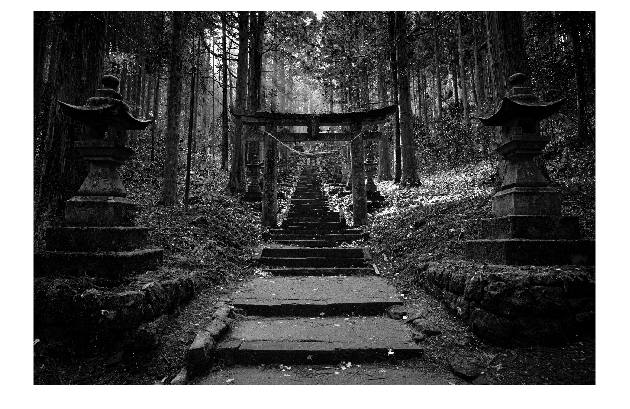

fftshow(cfli, "log");


c = 0.1;
"High pass filter, c = " + c

ans = "High pass filter, c = 0.1"

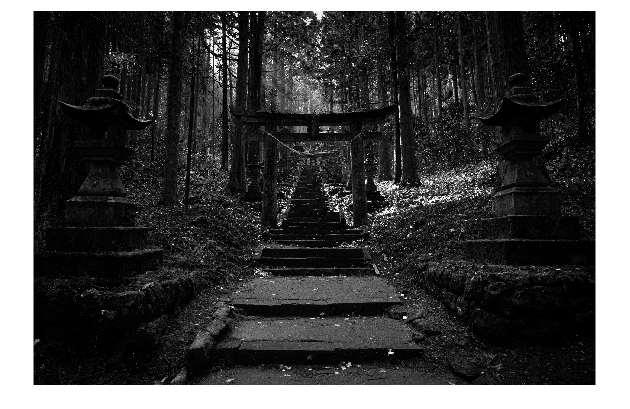

cfh = cf.*c;
cfhi = ifft2(cfh);
figure,fftshow(cfhi, "abs")

function fftshow = fftshow(f, type)
    if (type=="log" || nargin < 2)
        fl = log(1+abs(f));
        fm = max(fl(:));
        imshow(im2uint8(fl/fm))
    elseif (type=="abs")
        fa=abs(f);
        fm=max(fa(:));
        imshow(fa/fm)
    else
        error("TYPE must be abs or log.");
    end
end